# InputFile

Mit diesem Programm kann man die Schnittkräfte sowie die Auflagerreaktionen ermitteln aber auch Einflusslinien für jegliche Systeme bestimmen.

Im ersten Teil wird das System aufgebaut (Schritte 1 bis 7). Unter **Schritt 8** wird der **gewünschte Output gewählt** (Schnittkräfte/Auflagerreaktionen/Einflusslinie). Entsprechend wird dann der Teil mit den Lasten (Schritt 9 bis 11) oder der Teil für die Einflusslinie (Schritt 12 bis 14) bearbeitet.

Sobald das InputFile fertig ausgefüllt wurde, kann im *Command Window* der **Befehl ** `MatrizenStatik(0)` aufgerufen werden und der **gewünschte Output wird angezeigt.**

Achte darauf, dass dir die files *MatrizenStatik*.*m*, *InputFile.mlx *und die Ordner 'DSM', 'Input', 'Output' und 'Zeichnen' im *Current* *Folder* angezeigt werden. Falls dies nicht der Fall ist, wähle in der Zeile unter dem Toolstrip den richtigen Pfad aus (DSM-und-Eifnlusslinien -> src -> MatrizenStatik).

Es sind ein paar Beispiele hinterlegt. Welches InputFile und welchen case du dafür aufrufen musst, siehst du im file *ModelVonInputFile.m* im Ordner *Input. *Du kannst für die Ausgabe den Befehl  `MatrizenStatik(``case``)` aufrufen.

clear all; 
close all;

## Systemaufbau

### 1.Knoten

Gebe die x und y Koordinaten der Knoten entsprechend ein. Die Werte an der ersten Stelle entsprechen jeweils der x- resp. y-Koordinate des ersten Knotens etc. Zurzeit sind die Knoten 1 an Stelle (0|0), Knoten 2 an Stelle (0|1) und Knoten 3 an Stelle (0|2) eingegeben. Ändere diese und erstelle die weiteren Knoten deines Systems. Die Werte werden dabei **mit einem Komma getrennt**. Es ist dir überlassen, welche Einheiten du wählst, solang du konstant bleibst. Falls L keine Einheiten aufweist, kannst du beispielsweise L = 1 wählen.

%AUSFÜLLEN
xPos = [0,0,0]';
yPos = [0,1,2]';

Knoten = table(xPos,yPos)

Knoten = 3×2 table
    xPos    yPos
    ____    ____

     0       0  
     0       1  
     0       2  


in.Knoten = Knoten;

### 2.Stäbe

Die Knoten hast du nun erstellt. Wenn du auf *Run* drückst, siehst du diese in einer Tabelle. Nun erstellst du deine Stäbe. Dabei wählst du für einen Stab an welchem Knoten dieser anfängt und erfasst diesen Knoten unter StartKnoten. Dann wählst du an welchem Knoten der Stab aufhört und erfasst dies unter EndKnoten. Danach wählst du welchen Querschnitt dieser Stab aufweist. Die Querschnitte können in Schritt 3 erstellt werden.

Die Werte an der ersten Stelle gehören zum ersten Stab, die an der zweiten Stelle zum zweiten etc. Ändere die vorhandenen Wert und erstelle weitere Stäbe entsprechend deinem System. Wenn du auf *Run* drückst werden deine erstellten Stäbe in der Tabelle ersichtlich sein.

%AUSFÜLLEN
StartKnoten = [1,2]';
EndKnoten   = [2,3]';
Querschnitt = [1,1]';

Staebe = table(StartKnoten, EndKnoten, Querschnitt)

Staebe = 2×3 table
    StartKnoten    EndKnoten    Querschnitt
    ___________    _________    ___________

         1             2             1     
         2             3             1     


in.Staebe = Staebe;

### 3.Querschnitte

In diesem Schritt werden Querschnitte mit spezifischen Eigenschaften erstellt. Dies dient dazu, dass du nicht für jeden Stab jede Eigenschaft neu definieren musst, wenn du viele Stäbe mit den gleichen Eigenschaften hast. Falls du keine Einheiten für E, A und I hast, kannst du diese beispielsweise gleich 1 wählen.

Wenn dein Stab **dehnstarr** ist, dann wähle einen grossen Wert für A wie  A = 10^10 

Wenn dein Stab **biegestarr** ist, dann wähle einen grossen Wert für I wie I = 10^10

Wenn dein Stab keine Gelenke an den Enden aufweist, wähle jeweils 0. Für ein Normalkraftgelenk wähle 1, für Querkraftgelenk 2 und für ein Momentengelenk 3

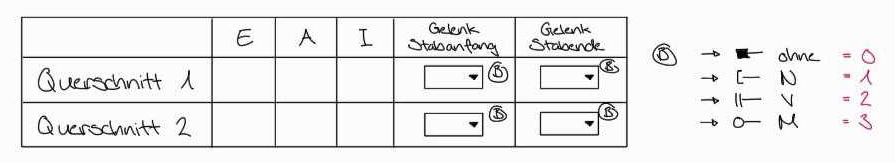

Die Werte an der ersten Stelle entpsrechen Querschnitt Nr.1 etc. **Trenne** die Werte **mit einem Komma**

%AUSFÜLLEN
EModul           = [1]';
Flaeche          = [10^10]'; 
Traegheitsmoment = [1]'; 
GelenkStabAnfang = [0]';  
GelenkStabende   = [0]';

table(EModul,Flaeche,Traegheitsmoment,GelenkStabAnfang,GelenkStabende)

ans = 1×5 table
    EModul    Flaeche    Traegheitsmoment    GelenkStabAnfang    GelenkStabende
    ______    _______    ________________    ________________    ______________

      1        1e+10            1                   0                  0       


Die folgenden 4 Zeilen bitte nicht ändern oder löschen! Sie dienen weiterführenden Arbeiten.

nQuerschnitte = size(EModul,1);
dehnstarr = false(nQuerschnitte,1);
biegesteif = false(nQuerschnitte,1);
in.Querschnitte = table(EModul, Flaeche, Traegheitsmoment, GelenkStabAnfang, GelenkStabende, dehnstarr, biegesteif);

### 4.Lager

Nun werden die Lager erstellt. Dabei stehen folgende Lager zur Auswahl:

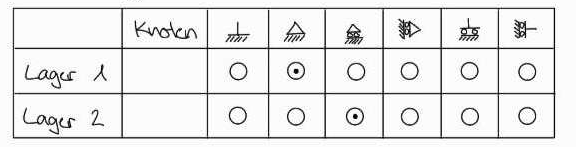

Zuerst bestimmst du an welchen Knöten ein Lager erstellt wird. Danach kannst du in den logical-Ausdrücken den Typ deines Lagers festlegen. Setze die 1 an der entsprechenden Stelle. Achte darauf, dass du soviele logical Ausrücke hast wie Anzahl Lager. Die logical Ausdrücke müssen wie folgt geschrieben werden: `logical([0,0,0,0,1,0]); `die 1 wird dabei an der Stelle des entsprechenden Lagers gesetzt. Die Lagerung ist in einem Vektor gespeichert, also falls du das löscht, vergiss nicht, es wieder als Vektor zu schreiben.

%AUSFÜLLEN
Knoten = [1,2]';
Lagerung = [logical([1,0,0,0,0,0]);
            %logical([1,0,0,0,0,0]);
            logical([0,0,1,0,0,0])];

Lager = table(Knoten,Lagerung)

Lager = 2×2 table
    Knoten     Lagerung  
    ______    ___________

      1       1×6 logical
      2       1×6 logical


in.Lager = Lager;

### 5.Feder

Hier kannst du Federn erstellen. Dafür wählst du an welchem Knoten die Feder angreift und unter Feder gibst du ein in welche Richtung die Feder wirkt. Das heist du wählst 1 für eine Feder in horizontale Richtung, die 2 für eine in vertikale Richtung und 3 für eine Drehfeder. Danach gibst du die Steifigkeit k der Feder unter Betrag ein.

Auch hier werden alle Werte für mehrere Federn mit einem Komma getrennt.

%AUSFÜLLEN, wenn vorhanden
Knoten = []';
Feder  = []';
Betrag = []';

Feder = table(Knoten, Feder, Betrag)


Feder =

  0×3 empty table



in.Feder = Feder;

### 6.Zwängungen

Falls Zwänungen also vorgeschriebene Verschiebungen in deinem System auftreten kannst du diese hier erfassen. Wähle dafür zuerst den Knoten. Danach kannst du die Richtung eingeben wobei 1 einer horizontalen Verschiebung, 2 einer vertikalen und 3 einer Drehung entspricht. Zum Schluss wird der Wert gesetzt. Achtung: Das Vorzeichen wird unter Wert berücksichtigt (also wähle nicht für die Richtung -3 für eine negative Drehung)

%AUSFÜLLEN, wenn vorhanden
Knoten   = []';
Richtung = []';
Wert     = []';

VorgeschriebeneVerschiebung = table(Knoten, Richtung, Wert)


VorgeschriebeneVerschiebung =

  0×3 empty table



in.VorgeschriebeneVerschiebung = VorgeschriebeneVerschiebung;

### 7.Teilsysteme

Dieser Schritt kann übersprungen werden. Wenn du dich jedoch für Teilsysteme interessierst, kannst du dich damit befassen.

In diesem Schritt kannst du mehrere Stäbe zu einem Superelement zusammenfassen, wie im Unterricht behandelt. Halte dabei die Reihenfolge wie die Stäbe aneinander gereiht sind ein. Die beiden Enden des Superelements werden herausgefiltert und damit weitergerechnet. Dadurch wird die DSM schlussendlich mit einer kleineren Systemsteifigkeitsmatrix durchgeführt.

Die Teilsysteme werden in Vektoren erfasst und z.B. wie folgt eingegeben: 

`BeteiligteStaebe = {[1,2,3],[5,6]};`

%AUSFÜLLEN, wenn Stäbe zu einem Teilsystem zusammengefasst werden sollen
BeteiligteStaebe = {};
in.Teilsysteme = BeteiligteStaebe;

## Definiere Output

### 8.Schnittkräfte oder Einflusslinie

Hier definierst du welchen Output du möchtest. Wähle die entsprechende Nummer!

1: gibt **Schnittkräfte** aus. Falls du die Schnittkräfte ausrechnen möchtest **bearbeite die Schritte 9 bis 11**

2: gibt die **Einflusslinie** aus. **Überspringe** dafür die **Schritte 9 bis 11** und **bearbeite die restlichen Schritte**

3: zeichnet die **Auflagerreaktionen**. **Bearbeite** dafür die **Schritte 9 bis 11**

%AUSFÜLLEN
in.gew_output = 2; % 1: Schnittkräfte | 2: Einflusslinie | 3: Auflagerreaktionen

## Lasten

### 9.Knotenlasten

Hier werden Knotenlasten erfasst, falls welche vorhanden sind. Die Lasten werden **im globalen Koordinatensystem** erfasst. Trenne die Werte mit einem Komma.

%AUSFÜLLEN, wenn vorhanden
Knoten   = []'; 
Richtung = []'; 
Wert     = []';

KnotenLasten = table(Knoten, Richtung, Wert)


KnotenLasten =

  0×3 empty table



in.KnotenLasten = KnotenLasten;

### 10.konzentrierte Stablasten

Hier werden konzentrierte Stablasten erfasst. Diese werden** im lokalen Koordinatensystems des Stabes** erfasst. Dabei spielt die Ausrichtung des Stabes eine Rolle (Dies hängt davon ab, welchen Knoten du als StartKnoten gewählt hast und welchen als EndKnoten). Für die Richtung kannst du 1,2 oder 3 wählen, wobei diese den Richtungen im lokalen KS entsprechen! Die **StartPosition** wird **in Abhängigkeit von L** angegeben. Achtung: Pass auf das Vorzeichen des Wertes auf. 

%AUSFÜLLEN, wenn vorhanden
Stab          = []';
Richtung      = []'; 
Wert          = []'; 
StartPosition = []'; % 0 < StartPosition < 1

StabLasten_konzentriert = table(Stab, Richtung, Wert, StartPosition)


StabLasten_konzentriert =

  0×4 empty table



in.StabLasten_konzentriert = StabLasten_konzentriert;

### 11.verteilte Stablasten

Hier werden verteile Stablasten erfasst. Diese werden** im lokalen Koordinatensystems des Stabes** erfasst. Dabei spielt die Ausrichtung des Stabes eine Rolle (Dies hängt davon ab, welchen Knoten du als StartKnoten gewählt hast und welchen als EndKnoten). Für die Richtung kannst du 1,2 oder 3 wählen, wobei diese den Richtungen im lokalen KS entsprechen! Eine verteilte Stablast muss sich nicht über den ganzen Stab erstrecken, aber falls doch wählst du für die StartPosition 0 und für die EndPosition 1. Die **StartPosition **sowie die** EndPosition** wird **in Abhängigkeit von L** angegeben. Achtung: Pass auf das Vorzeichen des Wertes auf. 

%AUSFÜLLEN, wenn vorhanden
Stab          = []'; 
Richtung      = []'; 
Wert          = []'; 
StartPosition = []'; % 0 <= StartPosition < 1
EndPosition   = []'; % 0 < StartPosition <= 1

StabLasten_verteilt = table(Stab, Richtung, Wert, StartPosition, EndPosition)


StabLasten_verteilt =

  0×5 empty table



in.StabLasten_verteilt = StabLasten_verteilt;

## Einflusslinie

### 12.Art der Einflusslinie

Hier kannst du die Art der Einflusslinie wählen. Wähle die entsprechende Nummer der gewünschten Art:

1: Einflusslinie für die **Normalkraft**. Bearbeite **Schritt 14**.

2: Einflusslinie für die **Querkraft**. Bearbeite **Schritt 14**.

3: Einflusslinie für das **Biegemoment**. Bearbeite **Schritt 14**.

4: Einflusslinie für eine **Lagerreaktion**. Bearbeite **Schritt 13**.

%AUSFÜLLEN, wenn Einflusslinie gesucht
TypEL = [4]; % 1:N, 2:V, 3:M, 4:Lager

#### 13.Einflusslinie für eine Lagerreaktion

Hier wählst du an welchem Knoten sich das Lager befindet. Danach auf welche Richtung sich die Lagerreaktion bezieht. Also 1,2 oder 3.

if TypEL == 4
  %AUSFÜLLEN, wenn Einflusslinie für Lagerreaktion gesucht
  Knoten   = [3];
  Richtung = [2];

 in.Einflusslinie = table(TypEL, Knoten, Richtung);

#### 14.Einflusslinie für eine Schnittgrösse

Hier wählst du an welchem Stab sich deine gewünschte Schnittgrösse befindet. Danach wählst du die **Stelle** **in Abhängigkeit von L**. Wenn du dich für eine Schnittgrösse direkt neben einem Knoten interessierst, wählst du einfach den Stab, an welcher sich diese Stelle befindet und danach 0 oder 1, je nach dem welchem Ende es entspricht.

else
  %AUSFÜLLEN, wenn Einflusslinie für Schnittgrösse gesucht
  Stab   = [2];
  Stelle = [0.5]; %zw. 0 <= x <= 1

in.Einflusslinie = table(TypEL, Stab, Stelle);
end

## Anmerkungen

- wenn du nur das System sehen willst dann rufe folgenden Befehl auf:  `drawFig(MatrizenStatik(X))`

- ändere das Format der Vektoren nicht, dies kann zu Fehler führen. Format wie folgt: `[..,..,..]'`

- vorgeschriebene Verschiebungen werden berechnet aber nicht gezeichnet

- Achtung: für Schnittkräfte könnten Probleme bei der Skalierung auftreten, je nach Wahl der verschiedenen Grössen. Also falls du keine Schnittkräfte siehst oder sie zu gross dargestellt werden kannst du im Ordner *Zeichnen *folgendes file öffnen: *drawSKFig.m* und dort die Zeile 24 einkommentieren und bearbeiten.

- bei den Auflagerreaktionen können Probleme mit der Skalierung der Vektoren auftreten. Die Werte die angezeigt werden stimmen jedoch. Z.B. kann das Moment zu klein gezeichnet werden, dass man es gar nicht sieht, obwohl es vorhanden ist. Achte daher auf den Wert der angezeigt wird.

- die Implementierung der Teilsysteme ist nicht vollständig. Daher können Probleme bei deren Einbindung entstehen.

- wenn du im *Workspace *auf *ans* drückst und dann weiter auf *Analyse* kannst du viele verschiedene Daten einsehen. Unter *SPC* findest du z.B. die Auflagerreaktionen. Unter *Stab* findest du alle Eigenschaften des Stabes sowie in den letzten Spalten die globalen und lokalen Verschiebungen des Stabes sowie die Stabendmomente in der Konvention des Koordinatensystems und in der letzen Zeile in der Schnittkraftkonvention (*q_loc_sk)*. Unter *K_sys *findest du auch die Systemsteifigkeitsmatrix. Beachte aber, dass die Lager erst später als SPC (Single Point Constraints) angebracht werden.

- wenn du ein neues InputFile erstellen möchtest für ein neues System ohne dieses zu löschen, führe folgende Schritte durch: 1.kopiere dieses InputFile indem du im Window *Current Folder *auf dieses File drückst und ihn kopierst. Nun kannst du Ctrl+V drücken. Dies fügt dir eine Kopie im Current Folder ein. Benenne das neue File um. Nun kannst du im Ordner *Input *im file *ModelVonInputFile *einen neuen case erstellen mit einer neuen Nummer und dein neues InputFile aufrufen.